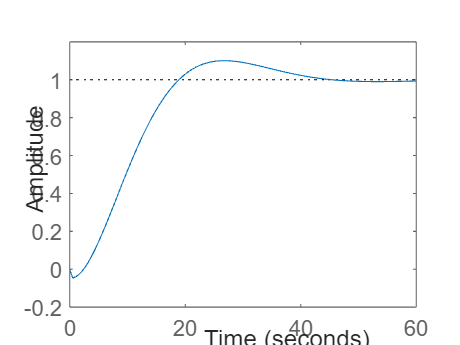

s = tf('s');
G_roll = -(13.89*s^2 + 3.34*s - 6.447)/(s^3 + 19.15*s^2 + 188.9*s + 33.71);
G_pitch = (-13.51*s^3 + 128.9*s^2 - 12.29*s + 2.041)/(s^4 + 19.23*s^3 + 173.3*s^2 + 454.9*s + 32.62);

% % Pitch
% % Kp_pitch = 0;
% % Ki_pitch = 0.324;
% % Kd_pitch = 0;
% 
% % Pitch Kp
% Kp_pitch_max = 7;
% Kp_pitch_min = 0;
% Kp_pitch_step = 0.5;
% 
% Kp_pitch = 2;
% 
% % Pitch Ki
% Ki_pitch_max = 1;
% Ki_pitch_min = 0;
% Ki_pitch_step = 0.1;
% 
% Ki_pitch = 0.2;
% 
% % Pitch Kd
% Kd_pitch_max = 0.1;
% Kd_pitch_min = 0;
% Kd_pitch_step = 0.0001;
% 
% Kd_pitch = 0.035;
% 
% controller_pitch = pid(Kp_pitch, Ki_pitch, Kd_pitch, Ts);
% open_loop_pitch = G_pitch*controller_pitch;
% closed_loop_pitch = feedback(open_loop_pitch, K);
% 
% step(closed_loop_pitch)

% % Roll
% Kp_roll = 7;
% Ki_roll = 0.5;
% Kd_roll = 0.0001;

% Roll Kp
Kp_roll_max = 7;
Kp_roll_min = 0;
Kp_roll_step = 0.5;

Kp_roll = 0;

% Pitch Ki
Ki_roll_max = 1;
Ki_roll_min = 0;
Ki_roll_step = 0.1;

Ki_roll = 0.6;

% Pitch Kd
Kd_roll_max = 0.1;
Kd_roll_min = 0;
Kd_roll_step = 0.0001;

Kd_roll = 0;

controller_roll = pid(Kp_roll, Ki_roll, Kd_roll, Ts);
open_loop_roll = G_roll*controller_roll;
closed_loop_roll = feedback(open_loop_roll, K);

step(closed_loop_roll)